We look at the balance between the axial spring and the magnet to lock the claw in position axially

clear
clf

considering a constant spring constant we get the pull of one **axial spring** from SODEMANN

k_axial = 0.29e3; % N/mm --> N/m % max kraft 47,43, max vandring 140,97, total lenth 229,87
% varenummer 	E07500633500S trækfjeder SODEMANN
x_axial = 140e-3; % udspændt fjeder til træk af claw
F_spring_axial = k_axial * x_axial

F_spring_axial = 40.6000

Magnet axial lock force

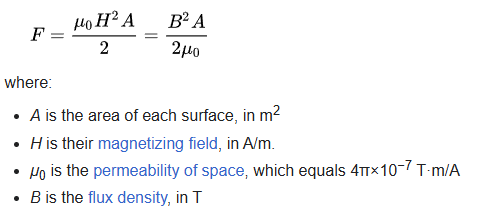

https://en.wikipedia.org/wiki/Force_between_magnets

g = 9.82;
x_contact = 1.85e-4; % "contact" point between the magnets (closest point)
d_magnet = 27e-3; %diameter of magnet
%chrome-extension://efaidnbmnnnibpcajpcglclefindmkaj/https://www.supermagnete.dk/data_sheet_CS-S-27-04-N.pdf
r_magnet = d_magnet/2; %radius of magnet
L = 4e-3; % https://www.supermagnete.dk/magneter-til-at-skrue-pa/skivemagnet-27mm-hjde-4mm_CS-S-27-04-N?group=lp-screwable-magnets
A = pi*(d_magnet/2)^2 %area of magnet surface

A = 5.7256e-04

mu = 1.25663706e-6; %(T·m)/A). Magnetic permability of air

kgF = 4; %kg  % the carry force of the magnet

We find an equation for the force of the magnetic field x distance away

syms B
F_magnet_in = kgF * g% / (1 + x_contact^2)

F_magnet_in = 39.2800

F_eq = F_magnet_in == B^2 * A / (2*mu); % force at contact point

B_sol = solve(F_eq, B);
B = double(B_sol(2))

B = 0.4152


x=x_contact

x = 1.8500e-04


F_magnet1 = ((B^2 * A^2 * (L^2 * r_magnet^2)) / (pi * mu * L^2)) * ...
    ( 1 / x^2 + 1 / (x+2*L)^2 - 2/(x+L)^2) %force between the two magnets

F_magnet1 = 75.9828

Frication acting on the calw is devided in to two kinds that are added up.

- Due to gravity we find

m_claw = 18; %kg <--------- differ between claws
f_s = 0.20; %static / kinetic friction coeffecient %steel on steel
F_claw_fric = g * m_claw * f_s

F_claw_fric = 35.3520

We sum the forces and add them

syms F_n_x
F_n_x_eq = 0 == F_spring_axial - F_magnet1 - F_claw_fric + F_n_x;

F_n_x_sol = solve(F_n_x_eq, F_n_x);
F_n_x_sol = double(F_n_x_sol)

F_n_x_sol = 70.7348

## plot

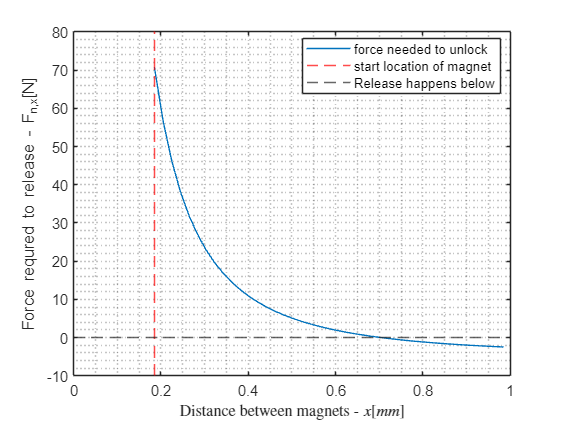

syms F_n_x
x_slut = 1e-3;
xs = x_contact:2e-5:x_slut; %Distance between magnets
for i = 1:length(xs)  
    F_magnet = ((B^2 * A^2 * (L^2 * r_magnet^2)) / (pi * mu * L^2)) *... 
    ( 1 / xs(i)^2 + 1 / (xs(i)+2*L)^2 - 2/(xs(i)+L)^2);

    x_axial = 140e-3 - xs(i); % udspændt fjeder til træk af claw
    F_spring_axial = k_axial * x_axial;

    F_n_x_eq = 0 == F_spring_axial - F_magnet - F_claw_fric + F_n_x;
    F_n_x_sol = solve(F_n_x_eq, F_n_x);

    F_n_x_sols(i) = double(F_n_x_sol);
    F_magnets(i) = F_magnet; % for later use
end

plot(xs*1000, F_n_x_sols, DisplayName="force needed to unlock")
hold on

xline(x_contact*1000,'r--', DisplayName="start location of magnet")
yline(0,'--', DisplayName="Release happens below")
xlabel("Distance between magnets - $x [mm]$", Interpreter="latex")
ylabel("Force requred to release - F_{n,x}[N]")
grid("minor")
legend(location='best')
hold off

**Release force**

phi = 45; % angle on claw slope

n_stack = 1; %number of stacked disc springs for more force
F_realese = 553 * n_stack; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s = 0.53e-3;
% tallerken fjeder vare nummer 1800-620-70

F_realease_x = sind(phi) * F_realese

F_realease_x = 391.0300


% T = F_realese * r
W = F_realese * s % The work the spring does on the rotor

W = 0.2931


syms omega
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-2
I = 15.9356; % inertia of the test motor % HMC4 355L-2 <--------- differ from motor to motor
W_eq = W == 1/2 * I * omega^2; % work of the rotor
omega_sol = solve(W_eq, omega);
omega = double(omega_sol(2))

omega = 0.1918

Dermed har jeg hastigheden ved slip, kraften aftager løbende i fjederen men antage at være tæt på F_realease_x i det kontakten slippes.

Couplings delen skal rejse 1 mm og tabet her negligeres

We see this as a elastic collision but beeing aware that some kinetik energi is lost to sound and heat.

m_rotor = 200; %                 <--------- differ from motor to motor
r = 0.09;%
u_rotor = r * omega

u_rotor = 0.0173

u_rotor_x = sind(phi) * u_rotor

u_rotor_x = 0.0122

% where u_claw = 0 since we are seeing it from the claws point of veiw.

% m_A·v_A1+m_2·v_B1=m_1·v_A2+m_2·v_B2
v_claw_x = u_rotor_x * (2*m_rotor)/(m_rotor+m_claw)

v_claw_x = 0.0224


F_claw = m_claw * v_claw_x / 0.1 % 0.02 symbolises the time the force is released

F_claw = 4.0312

% F_rotor = m_rotor * v_claw_x

F_move = (F_spring_axial - F_magnet1 - F_claw_fric + F_claw)

F_move = -66.9892

The magnet is too powerfull and no moment is seen. The small force applied by the claw requires too large of a balance.

x_axial_move = x_slut; % 
E_kin_claw = 1/2 * m_claw * v_claw_x^2

E_kin_claw = 0.0045


% E_kin_claw = F_claw*s_claw
s_claw = E_kin_claw/F_move % if negative normal force will counter and no movement is done

s_claw = -6.7385e-05

Some energies for a better idea of scale

E_axial_spring = 1/2 * k_axial * (x_axial_move)^2 * 2 %two springs %

E_axial_spring = 2.9000e-04


Friction_work_done = F_claw_fric * x_axial_move

Friction_work_done = 0.0354

Magnetic_work_done = trapz(xs, F_magnets) % trapezoidal integration with matlab function

Magnetic_work_done = 0.0113

% Work done due to friction

Total = E_kin_claw + E_axial_spring - Magnetic_work_done - Friction_work_done

Total = -0.0419

F_fric = F_spring_axial * f_s

F_fric = 8.0629


double(omega_sol(2))

ans = 0.1918

r_outer = 0.1;

s_fric = 2*pi*r * 9/360

s_fric = 0.0141

W_fric = F_fric * s_fric

W_fric = 0.1140


energi_left = W - W_fric

energi_left = 0.1791


syms omega
W_eq = 1/2 * I * omega^2 ==  W - W_fric;
sol = solve(W_eq,omega);
sol_omega = double(sol(2))

sol_omega = 0.1499


t = 2; %sek
s = sol_omega*r_outer*t

s = 0.0300